close all
clear all

A=[1 0.2;0 1];
B=[0;0.2];
C=[0.6 -0.2];
D=0;

## Q1. Unconstrained MPC

n=size(A,2);
m=size(B,2);

% Weightings in the quadratic cost
Q=C'*C;
R=eye(m,m); % this is a default value which can to be tuned to adjust the performances -- discuss this possibility


%!!!!!!!! to be completed - START !!!!!!!!!
N= 20    ;% choose the prediction horizon: this can be modified with differnet values for the analysis
P= Q     ;% choose the weighting of x(k+N)
%!!!!!!!! to be completed -  END  !!!!!!!!


In the first part of the TP we wrote P = 0 and then, P = Q we saw that there is no big difference, so we tried to change the value of N and we saw that when N is so big, the plot showed better and more accurate results.

Psi = P;
for i = 1:N-1
    Psi =  blkdiag(Q, Psi);
end

Phi = R;
for i = 1:N-1
    Phi =  blkdiag(R, Phi);
end


Pi = A;
for i = 1:N-1
    Pi = [Pi;
        A^(i+1)];
end

Gamma = B;
for j = 1:N-1
    Gamma = [zeros(n,m);Gamma];
end

for j = 1:N-1
    Gamma_temp = B;
    for i =1:j
        Gamma_temp = [Gamma_temp;A^(i)*B];
    end
    for i = j+1:N-1
        Gamma_temp = [zeros(n,m);Gamma_temp];
    end
    Gamma = [Gamma_temp, Gamma];
end

H = Phi + Gamma'*Psi*Gamma ;
F = Pi'*Psi*Gamma ;

X = [1;0] % initial state x(0)

X =      1
     0



tsim=100; % the legth of the simulation
Umem = [];
for i = 1:tsim
    U = quadprog(H,F'*X(:,end));
    X = [X A*X(:,end) + B*U(1:m)];% for the points 1.1b and beyound you may replace the control action by    (-G)*X(:,end)
    Umem = [Umem U];
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


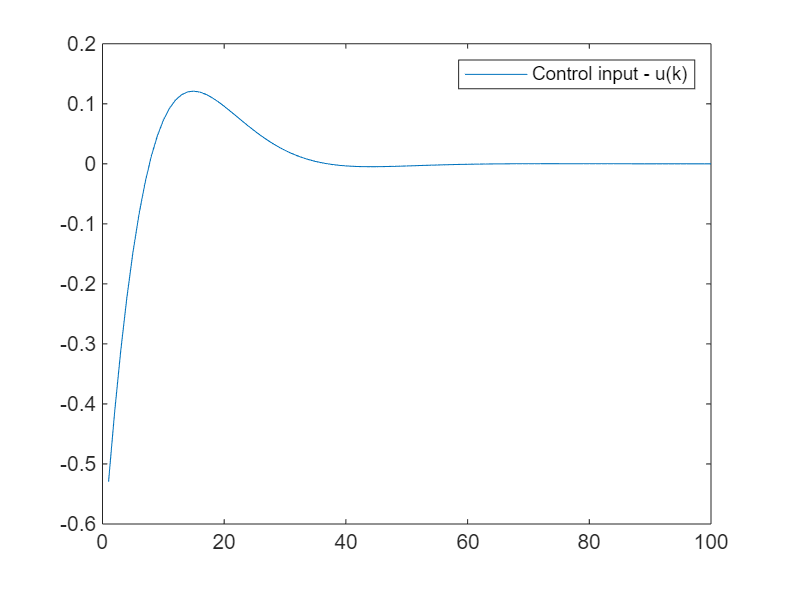


figure
plot(Umem(1,:))
legend('Control input - u(k)')

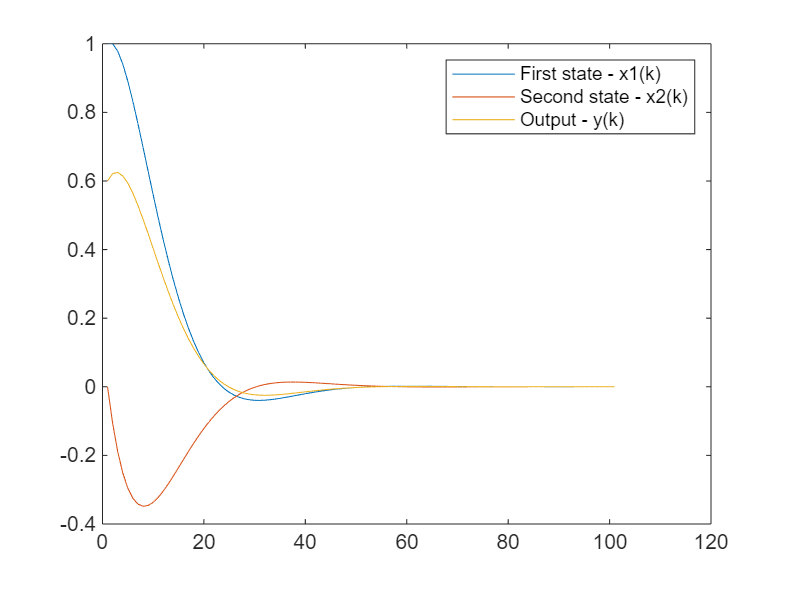

figure
plot(X(1,:));
hold on
plot(X(2,:));
plot(C*X)
legend('First state - x1(k)','Second state - x2(k)','Output - y(k)')

**b**: Analyze the stability of the closed-loop system.

% Define system matrices
A = [1, 0.2; 0, 1];
B = [0; 0.2];
C = [0.6, -0.2];

% Define optimization problem parameters
Q = C' * C; % State cost matrix
R = 1;      % Input cost matrix
N = 10;     % Prediction horizon

% Initialize
x0 = [1; 0]; % Initial state

% Dimensions
nx = size(A, 1); % State dimension
nu = size(B, 2); % Input dimension

% Define quadratic cost matrix (H)
Qbar = kron(eye(N+1), Q);             % Cost for states (N+1 steps)
Rbar = kron(eye(N), R);               % Cost for inputs (N steps)
H = blkdiag(Qbar, Rbar);              % Combined cost matrix
f = zeros(size(H, 1), 1);             % Linear cost vector (zero for quadratic programming)

% Equality constraints (Aeq * [x; u] = beq)
Aeq = zeros((N+1)*nx, (N+1)*nx + N*nu); % Aeq for [x; u]
beq = zeros((N+1)*nx, 1);               % Equality constraint vector

% Populate Aeq and beq
for i = 1:N
    % State evolution constraints
    Aeq((i*nx+1):(i+1)*nx, (i*nx+1):(i+1)*nx) = eye(nx);                   % x(k+1)
    Aeq((i*nx+1):(i+1)*nx, ((i-1)*nx+1):i*nx) = -A;                       % -A*x(k)
    Aeq((i*nx+1):(i+1)*nx, (N+1)*nx + ((i-1)*nu+1):(N+1)*nx + i*nu) = -B; % -B*u(k)
end
Aeq(1:nx, 1:nx) = eye(nx); % Initial state constraint
beq(1:nx) = x0;

% Solve the quadratic programming problem
options = optimoptions('quadprog', 'Display', 'off');
[x_u_opt, ~] = quadprog(H, f, [], [], Aeq, beq, [], [], [], options);

% Extract optimal inputs and states
x_opt = reshape(x_u_opt(1:(N+1)*nx), nx, N+1);    % Optimal states
u_opt = reshape(x_u_opt((N+1)*nx+1:end), nu, N); % Optimal inputs

% Compute feedback gain K using LQR
[K, ~, ~] = dlqr(A, B, Q, R);

% Compute closed-loop system matrix
Acl = A - B * K;

% Check eigenvalues for stability
eig_values = eig(Acl);
disp('Eigenvalues of the closed-loop system:');

Eigenvalues of the closed-loop system:


disp(eig_values);

   0.8885 + 0.0950i
   0.8885 - 0.0950i



disp(K);

    0.5361    1.1149




% Stability check
if all(abs(eig_values) < 1)
    disp('The system is stable.');
else
    disp('The system is unstable.');
end

The system is stable.


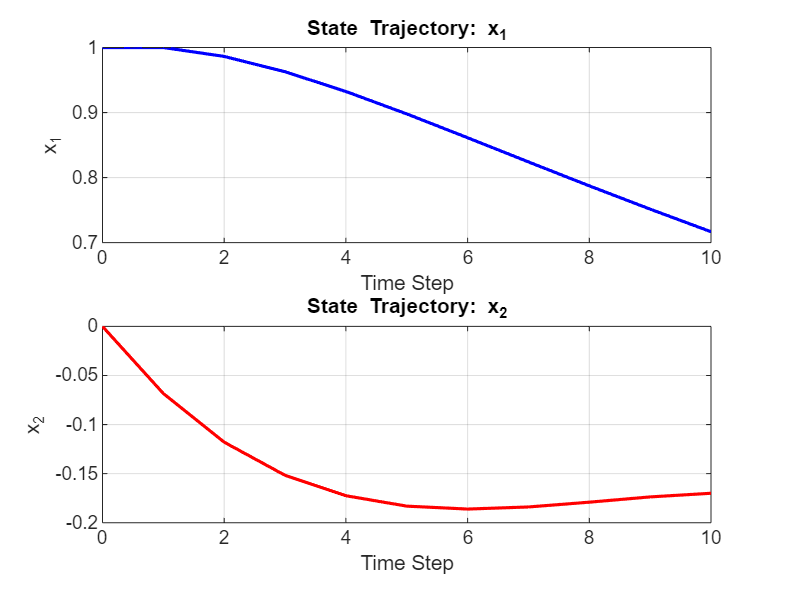


% Plot results
% Time vector
time = 0:N;

% Plot state trajectories
figure;
subplot(2, 1, 1);
plot(time, x_opt(1, :), 'b', 'LineWidth', 1.5);
title('State Trajectory: x_1');
xlabel('Time Step');
ylabel('x_1');
grid on;

subplot(2, 1, 2);
plot(time, x_opt(2, :), 'r', 'LineWidth', 1.5);
title('State Trajectory: x_2');
xlabel('Time Step');
ylabel('x_2');
grid on;

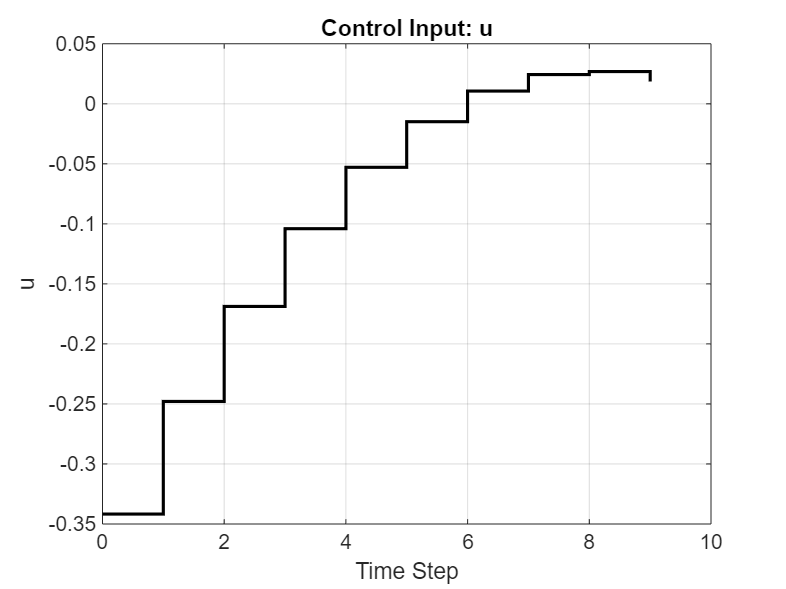


% Plot control input
figure;
stairs(0:N-1, u_opt, 'k', 'LineWidth', 1.5);
title('Control Input: u');
xlabel('Time Step');
ylabel('u');
grid on;

**c**: Analyze the change in performance for different prediction horizons.

% Define system matrices
A = [1, 0.2; 0, 1];
B = [0; 0.2];
C = [0.6, -0.2];

% Define optimization problem parameters
Q = C' * C; % State cost matrix
R = 1;      % Input cost matrix
N = 30;     % Prediction horizon

% Initialize
x0 = [1; 0]; % Initial state

% Dimensions
nx = size(A, 1); % State dimension
nu = size(B, 2); % Input dimension

% Define quadratic cost matrix (H)
Qbar = kron(eye(N+1), Q);             % Cost for states (N+1 steps)
Rbar = kron(eye(N), R);               % Cost for inputs (N steps)
H = blkdiag(Qbar, Rbar);              % Combined cost matrix
f = zeros(size(H, 1), 1);             % Linear cost vector (zero for quadratic programming)

% Equality constraints (Aeq * [x; u] = beq)
Aeq = zeros((N+1)*nx, (N+1)*nx + N*nu); % Aeq for [x; u]
beq = zeros((N+1)*nx, 1);               % Equality constraint vector

% Populate Aeq and beq
for i = 1:N
    % State evolution constraints
    Aeq((i*nx+1):(i+1)*nx, (i*nx+1):(i+1)*nx) = eye(nx);                   % x(k+1)
    Aeq((i*nx+1):(i+1)*nx, ((i-1)*nx+1):i*nx) = -A;                       % -A*x(k)
    Aeq((i*nx+1):(i+1)*nx, (N+1)*nx + ((i-1)*nu+1):(N+1)*nx + i*nu) = -B; % -B*u(k)
end
Aeq(1:nx, 1:nx) = eye(nx); % Initial state constraint
beq(1:nx) = x0;

% Solve the quadratic programming problem
options = optimoptions('quadprog', 'Display', 'off');
[x_u_opt, ~] = quadprog(H, f, [], [], Aeq, beq, [], [], [], options);

% Extract optimal inputs and states
x_opt = reshape(x_u_opt(1:(N+1)*nx), nx, N+1);    % Optimal states
u_opt = reshape(x_u_opt((N+1)*nx+1:end), nu, N); % Optimal inputs

% Compute feedback gain K using LQR
[K, ~, ~] = dlqr(A, B, Q, R);

% Compute closed-loop system matrix
Acl = A - B * K;

% Check eigenvalues for stability
eig_values = eig(Acl);
disp('Eigenvalues of the closed-loop system:');

Eigenvalues of the closed-loop system:


disp(K);

    0.5361    1.1149



disp(eig_values);

   0.8885 + 0.0950i
   0.8885 - 0.0950i




% Stability check
if all(abs(eig_values) < 1)
    disp('The system is stable.');
else
    disp('The system is unstable.');
end

The system is stable.


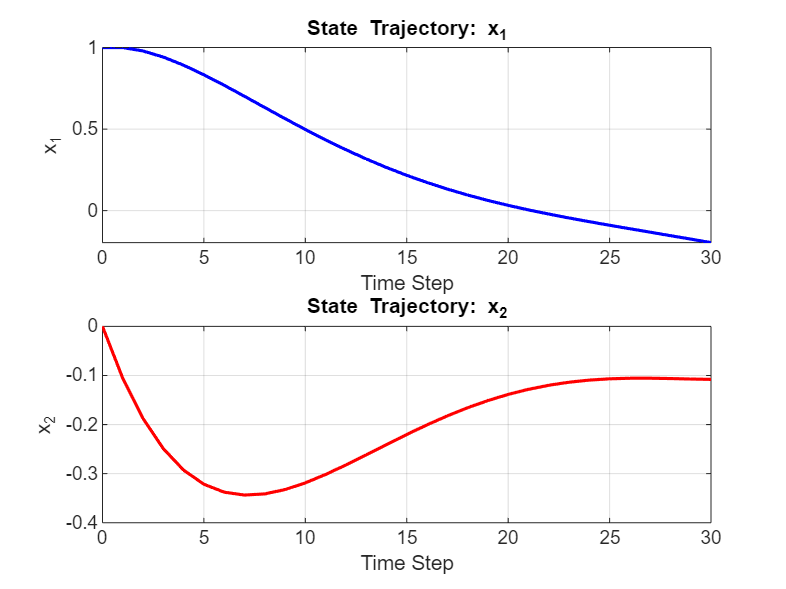


% Plot results
% Time vector
time = 0:N;

% Plot state trajectories
figure;
subplot(2, 1, 1);
plot(time, x_opt(1, :), 'b', 'LineWidth', 1.5);
title('State Trajectory: x_1');
xlabel('Time Step');
ylabel('x_1');
grid on;

subplot(2, 1, 2);
plot(time, x_opt(2, :), 'r', 'LineWidth', 1.5);
title('State Trajectory: x_2');
xlabel('Time Step');
ylabel('x_2');
grid on;

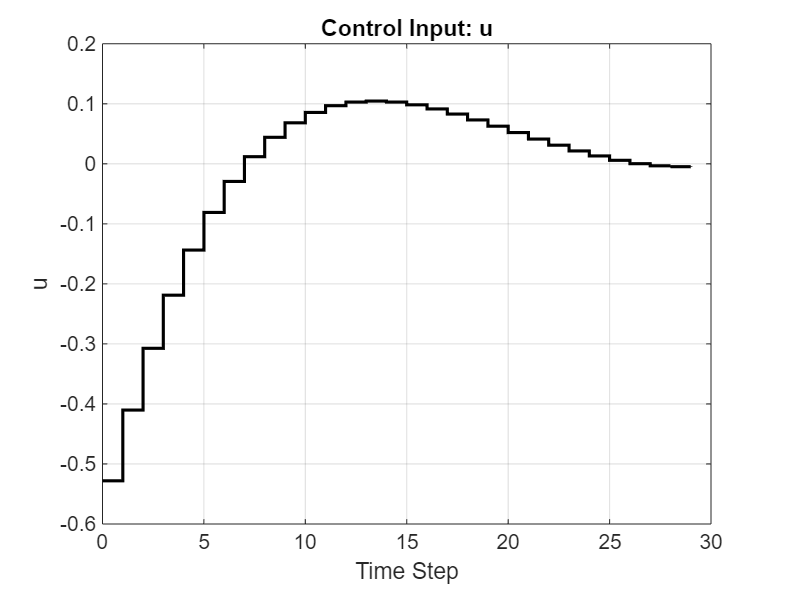


% Plot control input
figure;
stairs(0:N-1, u_opt, 'k', 'LineWidth', 1.5);
title('Control Input: u');
xlabel('Time Step');
ylabel('u');
grid on;

The prediction horizon 𝑁 determines how far into the future the MPC controller considers the system's behavior while solving the optimization problem.

A shorter prediction horizon may result in faster computation but may lead to suboptimal control actions and less robust behavior.

A longer prediction horizon can improve control performance by considering long-term effects but increases computational complexity.

## Q2. LQR

n=size(A,2);
m=size(B,2);

%!!!!!!!! to be completed - START !!!!!!!!!

% complete using the same simulation scenarion and replacing the MPC
% contrller with the LQR


%!!!!!!!! to be completed -  END  !!!!!!!!
%% Q2. LQR and MPC Comparison
close all;
clear all;

% Define system matrices
A = [1 0.2; 0 1];        % System dynamics matrix
B = [0; 0.2];            % Input matrix
C = [0.6 -0.2];          % Output matrix
Q = C' * C;              % State cost
R = 1;                   % Input cost

% Compute LQR gain using Algebraic Riccati Equation
[P, ~, K_lqr] = dare(A, B, Q, R); % LQR solution

% Initial state
x0 = [1; 0]; % Example initial condition

% Simulation parameters
tsim = 50; % Simulation length

% ----- LQR Simulation -----
x_lqr = x0; % Initialize state for LQR
u_lqr = []; % Store control inputs for LQR
y_lqr = []; % Store outputs for LQR

for k = 1:tsim
    u_k = -K_lqr * x_lqr(:, end);           % LQR control law
    u_lqr = [u_lqr, u_k];                  % Store control input
    x_next = A * x_lqr(:, end) + B * u_k;  % Update state
    x_lqr = [x_lqr, x_next];               % Store state
    y_lqr = [y_lqr, C * x_next];           % Store output
end

% ----- MPC Simulation -----
N = 30; % Prediction horizon for MPC

% Construct cost matrices for MPC
Psi = P;
for i = 1:N-1
    Psi = blkdiag(Q, Psi);
end

Phi = R;
for i = 1:N-1
    Phi = blkdiag(R, Phi);
end

Pi = A;
for i = 1:N-1
    Pi = [Pi; A^(i+1)];
end

Gamma = B;
for j = 1:N-1
    Gamma = [zeros(size(A, 1), size(B, 2)); Gamma];
end

for j = 1:N-1
    Gamma_temp = B;
    for i = 1:j
        Gamma_temp = [Gamma_temp; A^i * B];
    end
    for i = j+1:N-1
        Gamma_temp = [zeros(size(A, 1), size(B, 2)); Gamma_temp];
    end
    Gamma = [Gamma_temp, Gamma];
end

H = 2 * (Phi + Gamma' * Psi * Gamma); % Quadratic term
F = 2 * Pi' * Psi * Gamma;            % Linear term

% Initialize MPC states
x_mpc = x0; % Initialize state for MPC
u_mpc = []; % Store control inputs for MPC
y_mpc = []; % Store outputs for MPC

for k = 1:tsim
    f = F' * x_mpc(:, end);            % Linear term for QP
    U = quadprog(H, f, [], [], [], [], [], []); % Solve QP for MPC
    u_k = U(1);                        % Apply first input
    u_mpc = [u_mpc, u_k];              % Store control input
    x_next = A * x_mpc(:, end) + B * u_k; % Update state
    x_mpc = [x_mpc, x_next];           % Store state
    y_mpc = [y_mpc, C * x_next];       % Store output
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


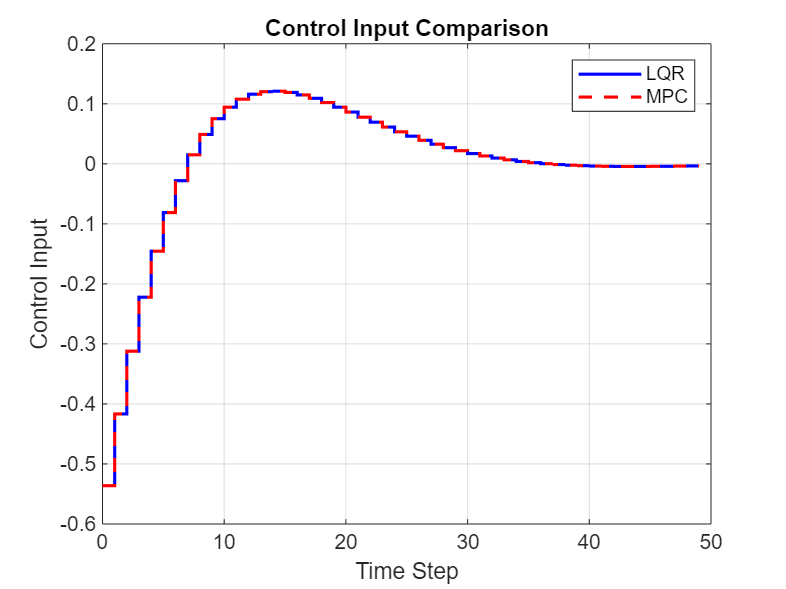


% ----- Plot Results -----
time = 0:tsim;

% Plot control inputs
figure;
stairs(0:tsim-1, u_lqr, 'b', 'LineWidth', 1.5);
hold on;
stairs(0:tsim-1, u_mpc, 'r--', 'LineWidth', 1.5);
title('Control Input Comparison');
xlabel('Time Step');
ylabel('Control Input');
legend('LQR', 'MPC');
grid on;

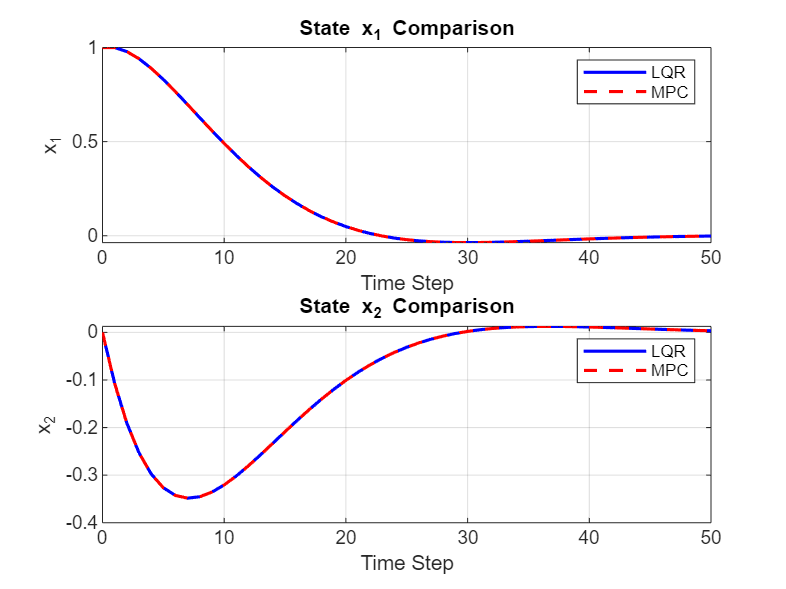


% Plot state trajectories
figure;
subplot(2, 1, 1);
plot(time, x_lqr(1, :), 'b', 'LineWidth', 1.5);
hold on;
plot(time, x_mpc(1, :), 'r--', 'LineWidth', 1.5);
title('State x_1 Comparison');
xlabel('Time Step');
ylabel('x_1');
legend('LQR', 'MPC');
grid on;

subplot(2, 1, 2);
plot(time, x_lqr(2, :), 'b', 'LineWidth', 1.5);
hold on;
plot(time, x_mpc(2, :), 'r--', 'LineWidth', 1.5);
title('State x_2 Comparison');
xlabel('Time Step');
ylabel('x_2');
legend('LQR', 'MPC');
grid on;

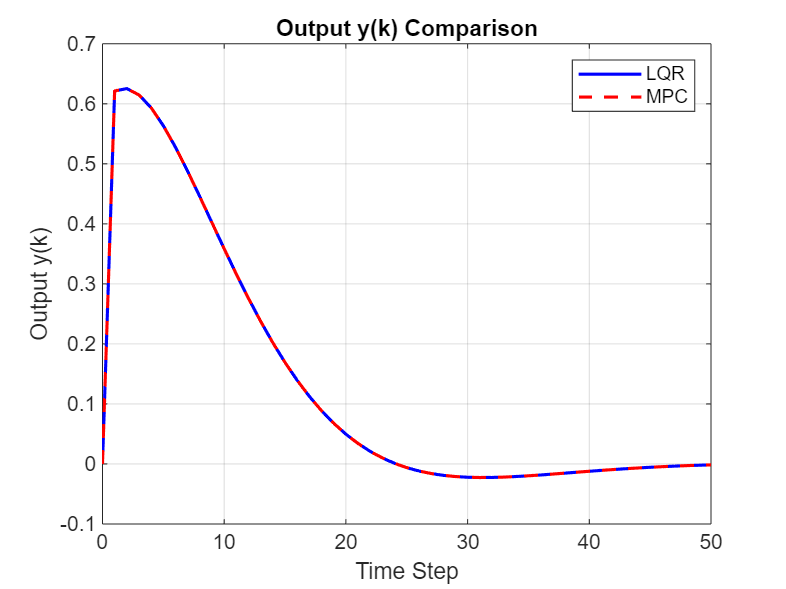


% Plot output trajectories
figure;
plot(time, [0, y_lqr], 'b', 'LineWidth', 1.5);
hold on;
plot(time, [0, y_mpc], 'r--', 'LineWidth', 1.5);
title('Output y(k) Comparison');
xlabel('Time Step');
ylabel('Output y(k)');
legend('LQR', 'MPC');
grid on;

1.2 

We find that both solutions are stable the difference here is that in LQR we fixed the gain K and the MPC is horizon dependent when it's short and near optimal when the horizon is long.

## Q3. MPC with terminal cost

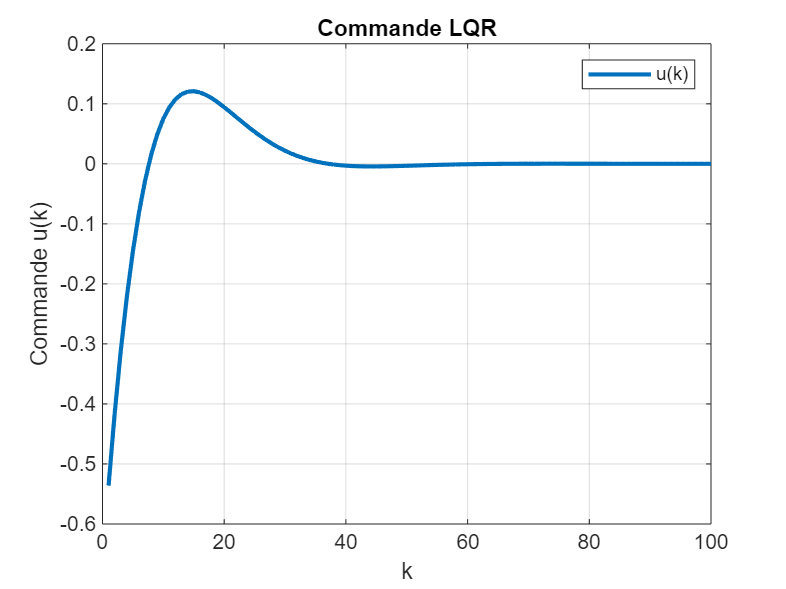

%!!!!!!!! to be completed - START !!!!!!!!!

%similar to Q1

%!!!!!!!! to be completed -  END  !!!!!!!!
clc;
clear;
close all;

% Définition du système
A = [1 0.2; 0 1];
B = [0; 0.2];
C = [0.6 -0.2];
D = 0;

n = size(A, 2); % Nombre d'états
m = size(B, 2); % Nombre d'entrées


Q = C' * C;     % Poids sur les états
R = eye(m, m);  % Poids sur les commandes

% Résolution de l'équation algébrique de Riccati
[X, L, G, report] = dare(A, B, Q, R);

K = -G; % Gain optimal pour LQR

% Initialisation
X_mem = [1; 0]; % État initial
U_mem = [];     % Commandes appliquées

% Simulation
tsim = 100; % Longueur de la simulation

for i = 1:tsim
    % Calcul de la commande avec LQR
    U = K * X_mem(:, end);
    
    % Mise à jour des états
    X_mem = [X_mem, A * X_mem(:, end) + B * U];
    U_mem = [U_mem, U];
end

% Tracé des résultats
figure;
plot(U_mem(1, :), 'LineWidth', 2);
xlabel('k');
ylabel('Commande u(k)');
title('Commande LQR');
legend('u(k)');
grid on;

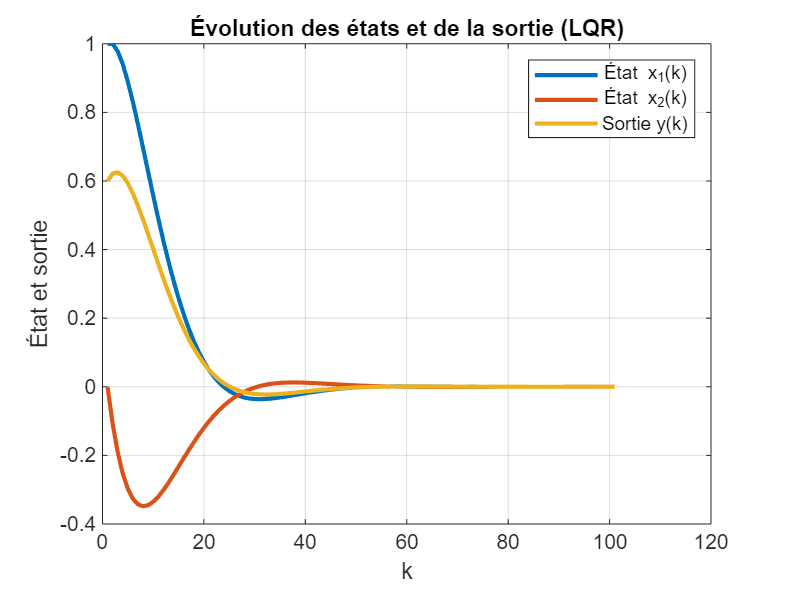


figure;
plot(X_mem(1, :), 'LineWidth', 2);
hold on;
plot(X_mem(2, :), 'LineWidth', 2);
plot(C * X_mem, 'LineWidth', 2);
xlabel('k');
ylabel('État et sortie');
title('Évolution des états et de la sortie (LQR)');
legend('État x_1(k)', 'État x_2(k)', 'Sortie y(k)');
grid on;

1.3 a 

The terminal cost improves stability by penalizing the deviation of the final state from the desired value, and also exhibit better robustness to disturbances, as the cost function explicitly accounts for long-term state behavior.

Smother Trajectory : The system converges more gracefully to the origin due to the terminal cost.

Faster Convergence: Adding the terminal cost accelerates convergence as it encourages the controller to steer the system closer to the origin at the end of the prediction horizon.

1.3 b 

Both MPC with terminal cost and LQR result in stable closed-loop systems, as confirmed by eigenvalues of (A−BK) lying inside the unit circle

The terminal cost in MPC ensures stability similar to LQR by aligning the cost function with the infinite-horizon optimal control.

## Q4. test of positive invariance

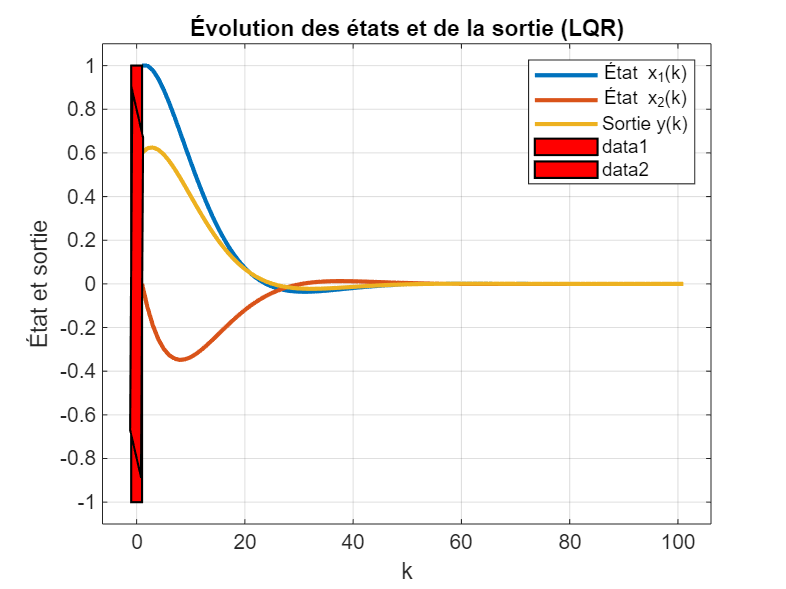

X=Polyhedron([eye(2);-eye(2)],[ones(2,1);ones(2,1)]);
X.plot;
hold on
plot((A-B*G)*X)

% System matrices
A = [1, 0.2; 0, 1];
B = [0; 0.2];
C = [0.6, -0.2];
Q = C' * C; % State cost matrix
R = 1;      % Input cost matrix

% Terminal cost from DARE
[P, ~, K_terminal] = dare(A, B, Q, R);

% Feedback gains for MPC
K_mpc_short = 0.5361 %gain from MPC (N = 10)

K_mpc_short = 0.5361

K_mpc_long = 1.1149  %gain from MPC (N = 30)

K_mpc_long = 1.1149

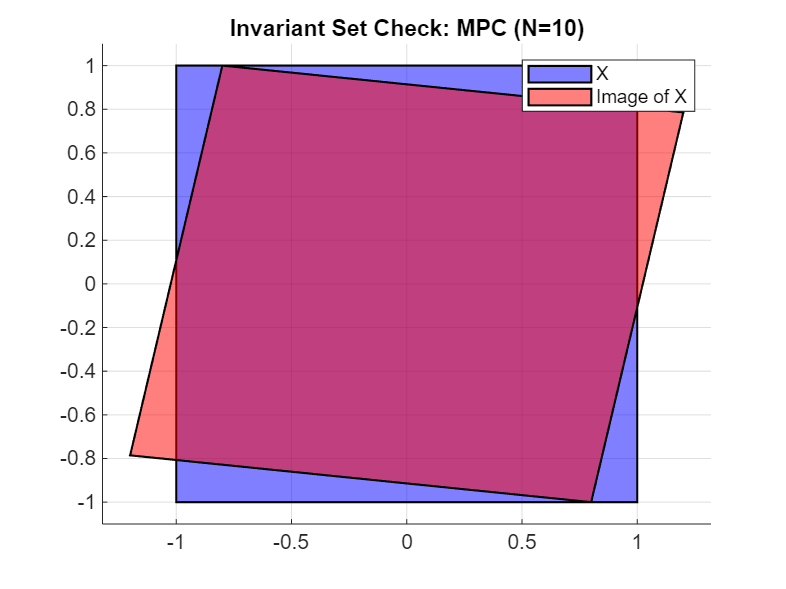

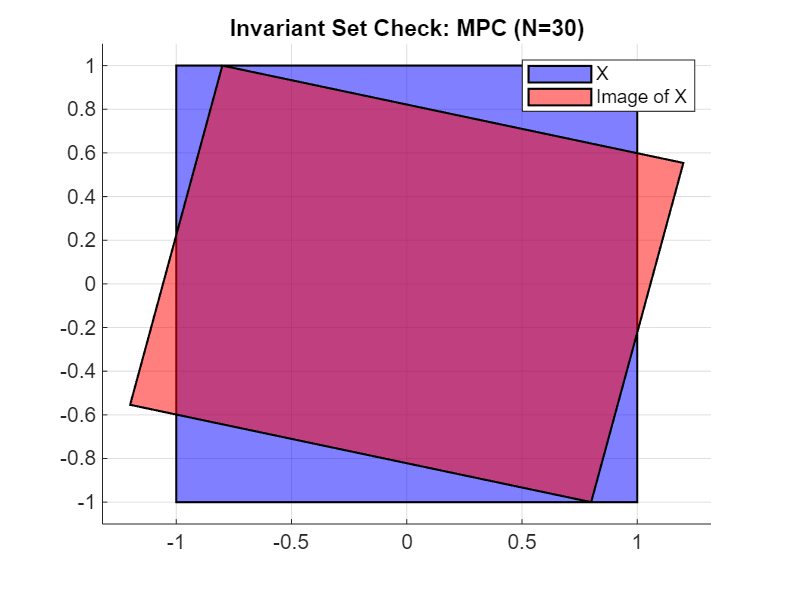

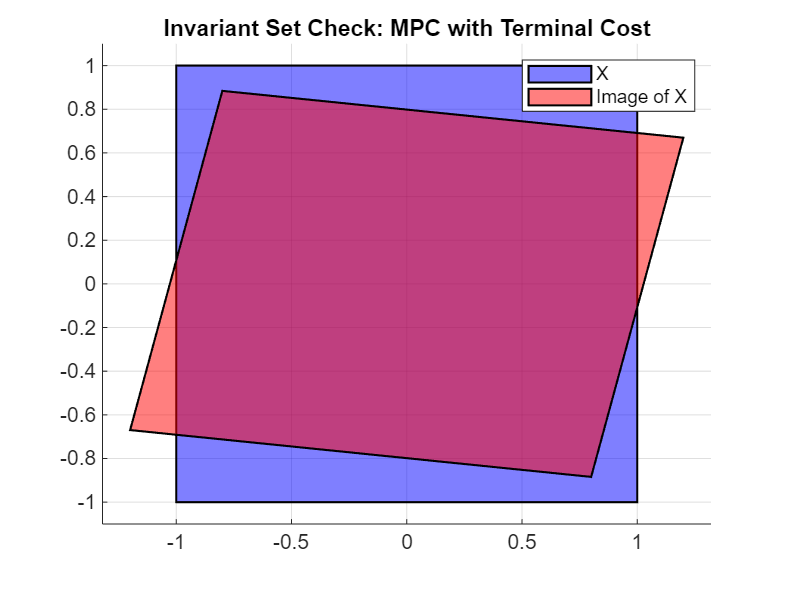


% Define state constraint set X
X = Polyhedron('lb', [-1; -1], 'ub', [1; 1]);

% Check invariance for each feedback gain
gains = {K_mpc_short, K_mpc_long, K_terminal};
titles = {'MPC (N=10)', 'MPC (N=30)', 'MPC with Terminal Cost'};
for i = 1:length(gains)
    K = gains{i};
    A_cl = A - B * K; % Closed-loop dynamics
    
    % Compute the image of X
    X_next = A_cl * X; % Use Polyhedron operation
    
    % Plot X and X_next
    figure;
    hold on;
    plot(X, 'Color', 'blue', 'Alpha', 0.5);
    plot(X_next, 'Color', 'red', 'Alpha', 0.5);
    title(['Invariant Set Check: ', titles{i}]);
    legend('X', 'Image of X');
    hold off;
end


% Prepare data for Bitsoris' Theorem
Hx=X.A; % the matrix composing the inequalities of the state constraints
w=X.b; % the right hand side of the inequalities describing the state constraints

%construct the varaible for the resolution of the set of linear
%inequalities + equalities
F=sdpvar(size(Hx,1),size(Hx,1),'full');

%!!!!!!!! to be completed - START !!!!!!!!!
Constraints=[F>=0, F*w<=w, Hx*(A-B*G) == F*Hx]  

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                     Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality 16x1|              1 to 1|
|   #2|    Element-wise inequality 4x1|              1 to 1|
|   #3|        Equality constraint 4x2|        0.10723 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


diagnostics = optimize(Constraints)

diagnostics = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2740171 (R2024b) Update 1'
       yalmiptime: NaN
       solvertime: NaN
             info: 'Unknown problem (<a href="yalmip.github.io/inside/debug">learn to debug</a>) (Unknown problem (<a href="yalmip.github.io/inside/debug">learn to debug</a>) (Error using linprog (line 99)↵LINPROG(f,A,b,Aeq,beq,LB,UB,X0,OPTIONS) does not accept X0. Use LINPROG(f,A,b,Aeq,beq,LB,UB,OPTIONS) instead.))'
          problem: 9


%%
%2nd try
eps = sdpvar;
h = -eps;
Constraints=[F>=0, F*w<=w - eps*ones(4,1), Hx*A == F*Hx]

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                     Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality 16x1|              1 to 1|
|   #2|    Element-wise inequality 4x1|              1 to 1|
|   #3|        Equality constraint 4x2|            0.2 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



diagnostics = optimize(Constraints, h, [])

diagnostics = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2740171 (R2024b) Update 1'
       yalmiptime: NaN
       solvertime: NaN
             info: 'Unknown problem (<a href="yalmip.github.io/inside/debug">learn to debug</a>) (Unknown problem (<a href="yalmip.github.io/inside/debug">learn to debug</a>) (Error using linprog (line 99)↵LINPROG(f,A,b,Aeq,beq,LB,UB,X0,OPTIONS) does not accept X0. Use LINPROG(f,A,b,Aeq,beq,LB,UB,OPTIONS) instead.))'
          problem: 9



value(eps)

ans = NaN


figure(2)
X=Polyhedron([eye(2);-eye(2)],[ones(2,1);ones(2,1)]);
plot((1+abs(value(eps)))*X)

Error using validate_realvector (line 10)
Input argument must be a real vector.

Error in  *  (line 61)
    validate_realvector(P);

hold on
plot((A-B*G)*X, 'color', 'b')

%%
%3rd try
B=[0.1;0.2]
eps = sdpvar(1);
%eps = sdpvar;
F=sdpvar(size(Hx,1),size(Hx,1),'full');
G=sdpvar(1,size(B,1),'full');
Constraints=[F>=0, F*w<=w + eps*ones(4,1), Hx*(A+B*G) == F*Hx]

diagnostics = optimize(Constraints,eps);%, h, [])

value(eps)
